# Operational Amplifier

- *Electric Circuits Virtual Labs *

- *Author: Zekeriya Aliyazicioglu, Dennis Dahlquist*

## Introduction

An operational amplifier (commonly called op-amp or OpAmp) is an integrated circuit (IC) that can be used to perform mathematical operations such as addition, subtraction, amplification, attenuation, integration, and differentiation. It is widely used in amplifiers, filters, signal conditioning, and instrumentation circuits.

## Learning Objectives

Will be able to analyze inverting, non-inverting, summing, and differencing operational amplifier circuits in the time domain. with MATLAB tools. 

## **Operational Amplifier (Op-Amp)**

The Op-Amp is an electronic unit that behaves like a voltage-controlled voltage source. The operational amplifier circuit is known as a basic building block circuit and basically used to implement the mathematical operation of integration, differentiation, addition, sign chance, and scaling. The most common op-amp is uA741, It may come in different packages

                  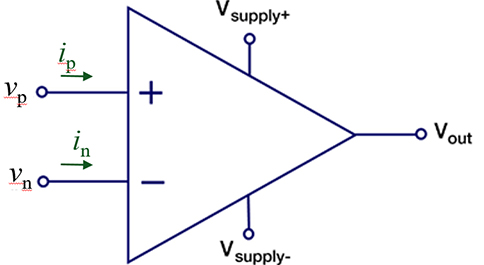       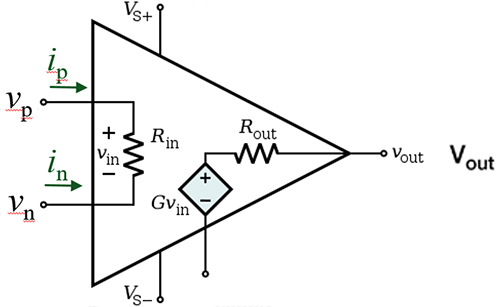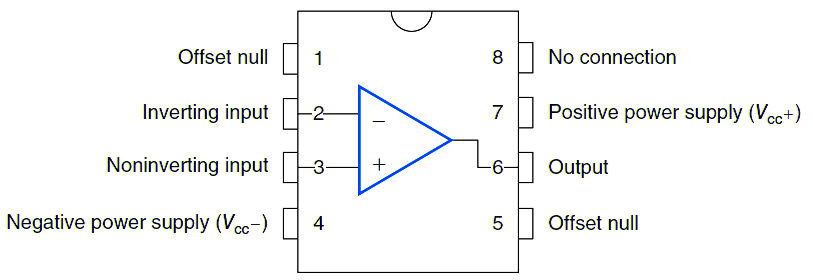

              Figure 1. a. Circuit symbol,  b.   An equivalent circuit of an operational, c. Pin configuration

In the model, $V_p$  is the voltage on the noninverting input (pin 3), $V_n$ is the voltage on the inverting input (pin 2), $V_{out}$ is the voltage on the output (pin ) of the op amp. $R_i$ is the input resistance, $R_{out}$ is the output resistance, and $G$ is the unloaded voltage gain. In general, the input resistance $R_i$ is large, the output resistance $R_{out}$ is small, the gain $G$ is large. For uAA741 operational amplifier, typical value of $R_i=2M\Omega$, $R_{out}=75\Omega$, and $G=200,000$ 

We use $R_i=\infty$, $R_{out}=0$, and $G=\infty$ for ideal case.   If an op amp is assumed to be ideal, the analysis of circuits with op amps is significantly simplified.

 Ideal case, we accept 

                        

The equivalent resistance seen by the input terminals of the op-amp is very large. Ideal case, we accept 

                        

Node: Op-amp has positive Vcc(+1) and negative Vcc (-) power supply. The output voltage value cannot be greater than Vcc(+) or less than Vcc(-). Vcc values are the threshold value. 

Let’s take the steps by considering the circuit below and find the node voltages $V_1, V_2$, and the current   $i_3$

                       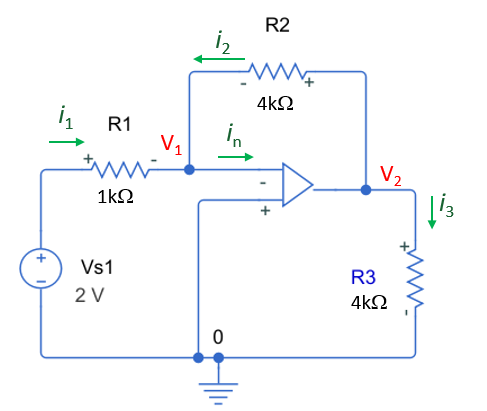

          Let's  write a node equation at Node1 $i_1+i_2-i_n=0$ . For ideal Ap-Amp$i_n=0$, and apply Ohm's law to $i_1$and $i_2$, Node equation becomes

                                      
$$\frac{V_{s1}-V_1}{R_1} +\frac{V_2-V_1}{R_f}=0$$


           Due to a virtual short, we have$V_1=V_n=V_p=0$

          Node equation becomes

                                         
$$\frac{V_{s1}}{R_1} +\frac{V_2}{R_f}=0$$


          Let's use MATLAB** solve** function to find V2 

u = symunit;

% Given Values
Vs1 = 2*u.V;
R1 = 1*u.kOhm; R2 = 4*u.kOhm; R3 = 4*u.kOhm;

% Known Node Voltage  V1
V1=0*u.V;

% Unknown Node voltage V2
syms V2;

% Node equations and solutions
[V2] = solve ((Vs1-V1)/R1+(V2-V1)/R2==0);
V2 = rewrite(V2,u.V)   % define as V

$$V2 = -8\,V$$

 Current $i_3$ can be calculated by 

                          
$$i_3=\frac{V_2}{R_3}$$


% Curent i3
i3=V2/R3;
i3 = rewrite(i3,u.mA)   % define as mA

$$i3 = -2\,\mathrm{mA}$$

**Alternative solution**: Solving $V_2$ from node equation, we obtain

                            
$$V_2=-\frac{R_f}{R_1}V_{s1}$$


Or using the final equation of  $V_2$ and $i_3$ can be calculated in MATLAB as 

u = symunit;

% Given Values
Vs1 = 2*u.V;
R1 = 1*u.kOhm; R2 = 4*u.kOhm; R3 = 4*u.kOhm;

% Known Node voltage V1
V1=0*u.V

$$V1 = \frac{1}{10}\,V$$


% Unknown Node voltage V2
V2 =-R2/R1*Vs1

$$V2 = -8\,V$$


% Curent i3
i3=V2/R3;
i3 = rewrite(i3,u.mA)   % define as mA

$$i3 = -2\,\mathrm{mA}$$

Circuit can be simulated  in MATLAB Simulink [./Simulink\Operational_Amplifier.slx](matlab:open('./Simulink\Operational_Amplifier.slx'))

        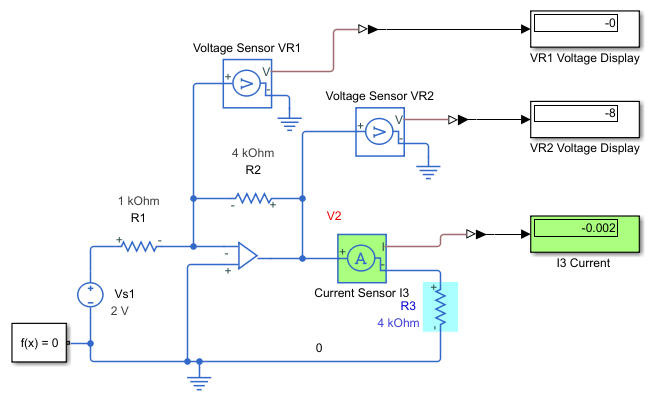

### Case 1:  Inverting and Noninverting Operational Amplifier Circuits

#### Example 1. Inverting Operational Amplifier Circuit

Find $$V_1, V_0$ in the circuit shown in Figure. Solve the problem in MATLAB Script. Simulate the circuit in Simulink to verify our results. 

                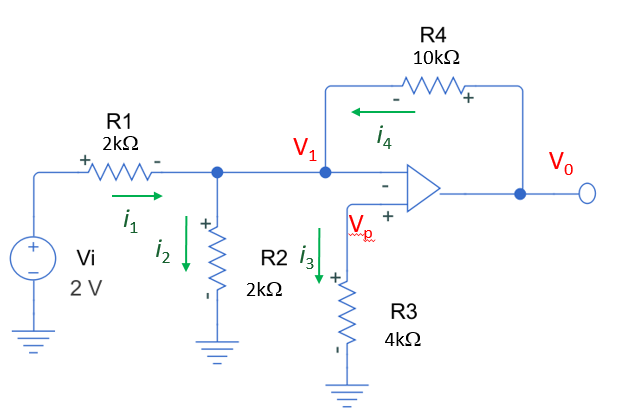

   **Solution**

    Let's  write a node equation at Node $V_1
$   $i_1-i_2+i_4-i_n=0$ . For ideal Ap-Amp $i_n=i_p=0$, and apply Ohm's law to $i_1$, $i_2$,and $i_4$. Node equation becomes

                                      
$$\frac{V_i-V_1}{R_1} -\frac{V_1}{R_2}+\frac{V_0-V_1}{R_4}=0$$


           Due to a virtual short, we have$V_1=V_n=V_p=0$  (since $i_p=0$, $i_3=i_p=0$ and $V_p=0$)

          Node equation becomes

                                        $\frac{V_i-0}{R_1} -\frac{0}{R_2}+\frac{V_0-0}{R_4}=0$, or          $\frac{V_i}{R_1} +\frac{V_0}{R_4}=0$

       Let's use MATLAB** solve** function to find $V_0$     

u = symunit;

% Given Values
Vi = 2*u.V;
R1 = 2*u.kOhm; R2 = 2*u.kOhm; R3 = 4*u.kOhm;R4 = 10*u.kOhm;

% Known Node Voltage  V1
V1=0*u.V;

% Unknown Node voltage V0
syms V0;

% Node equations and solutions
V0 = solve ((Vi-V1)/R1-V1/R2+(V0-V1)/R4==0)

$$V0 = -10\,V$$

V0 = vpa(V0,5)

$$V0 = -10.0\,V$$

 **Alternative solution: **Solving for $V_0$, we obtain

                            
$$V_0=-\frac{R_4}{R_1}V_i$$


u = symunit;

% Given Values
Vi = 2*u.V;
R1 = 2*u.kOhm; R2 = 2*u.kOhm; R3 = 4*u.kOhm;R4 = 10*u.kOhm;

% Known Node Voltage  V1
V1=0*u.V;

% Unknown Node voltage V0
V0 =-(R4/R1)*Vi

$$V0 = -10\,V$$

V0 = vpa(V0,5)

$$V0 = -10.0\,V$$

Finally we have the following values

$V_1=0V$,   $V_0 =-10 V$

Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_1.slx](matlab:open('./Simulink\Example_1.slx'))

        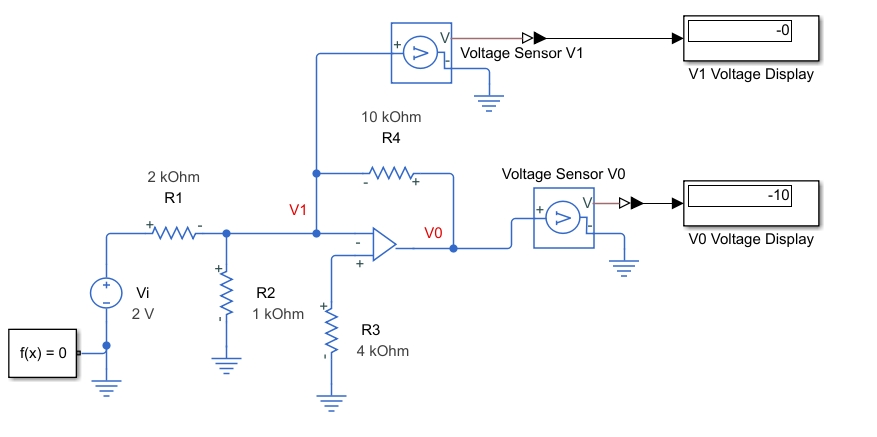

#### Exercise  1. Noninverting Operational Amplifier Circuit

Find $$V_1, V_0$ in the circuit shown in Figure. Solve the problem in MATLAB Script. Simulate the circuit in Simulink to verify our results. 

                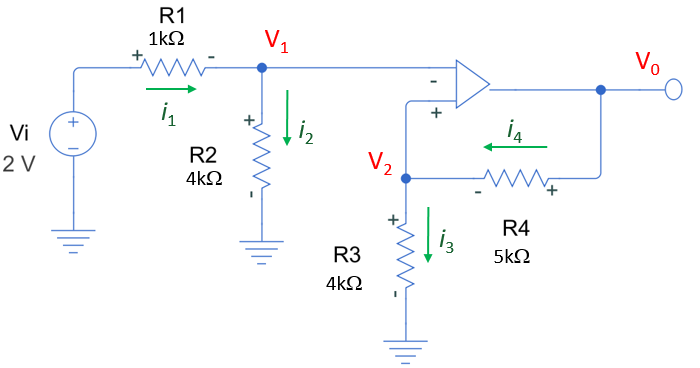

   **Solution**

    For ideal Ap-Amp $i_n=i_p=0$. Find $$V_1$ using voltage

    For ideal Ap-Amp  $V_n=V_p$. Find $$V_2$

    Write a node equation at Node $V_2
$ . 

    Apply Ohm's law to the currents. 

      Let's use MATLAB** solve** function to find $V_0$     

u = symunit;

% Given Values

% calculate Node Voltage  V1


% Unknown Node voltage V0
syms V0;

% Node equations and solutions


 **Alternative solution: **Solving  $V_0$ from previous node equation

u = symunit;

% Given Values


% Write Node Voltage  V1


% Write Node voltage V0
0

ans = 0

Circuit can be simulated  in MATLAB Simulink 

        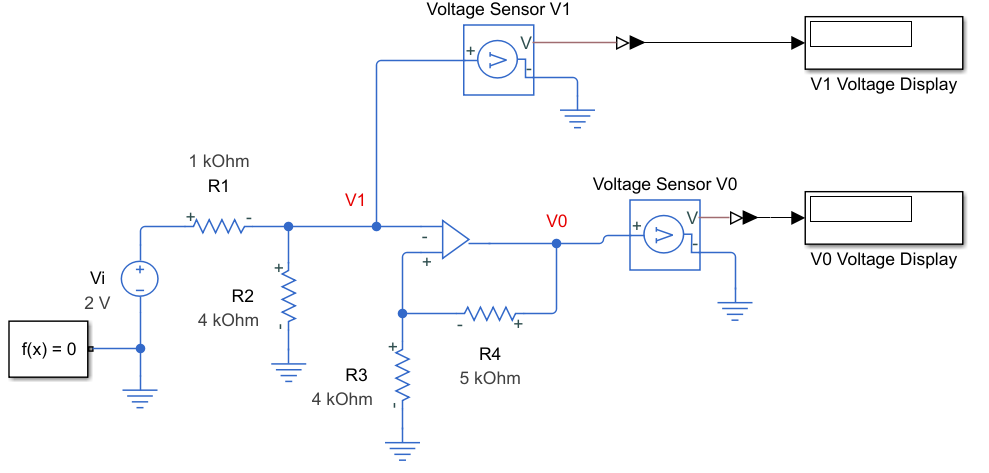

### Case 2:  Summing and Difference Operational Amplifier Circuits

Operation circuits that can be used to add input signals or subtract one signal from another. The summing amplifiers can be implemented in the inverting configuration or noninverting configuration.

#### Example 2.  Summing Operational Amplifier Circuit

In the following circuit

- Write a node equation at node $$V_{n1}$  to find $$V_3$.

- Write a node equation at node $$V_{n2}$  to find $$V_0$.

- If  resistor  $R_5=10k\Omega$,  what will be $$V_0$ ?

- If source $$V_1=2V$and resistor  $R_5=10k\Omega$, what will be $$V_0$ ?

                  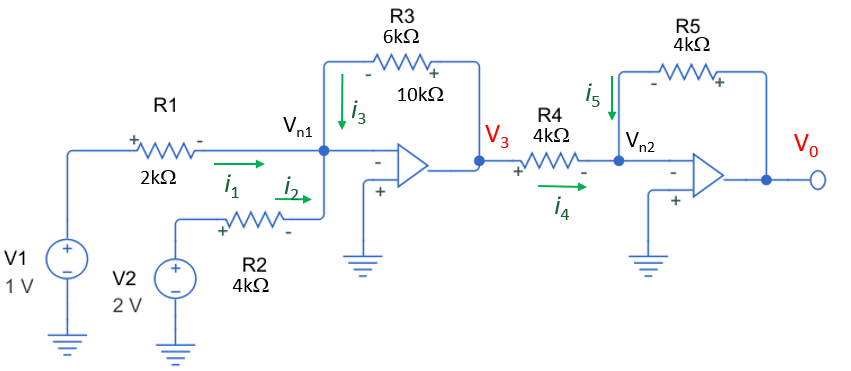

 **Solution**

       1. Let's  write a node equation at Node $$V_{n1}$.    $i_1+i_2+i_4-i_{n1}=0$ . For ideal Ap-Amp $i_n=i_p=0$, and  apply Ohm's law to $i_1$, $i_2$,and $i_3$. Node equation becomes

                                      
$$\frac{V_1-V_{n1}}{R_1} +\frac{V_2-V_{n1}}{R_2}+\frac{V_3-V_{n1}}{R_3}=0$$


           Due to a virtual short, we have$V_{n1}=V_{p1}=0$

          Node equation becomes

                                        $\frac{V_1}{R_1} +\frac{V_2}{R_2}+\frac{V_3}{R_3}=0$.

       Let's use MATLAB** solve** function to find $V_3$     .   

u = symunit;

% Given Values
V1 = 1*u.V

$$V1 = V$$

V2 = 2*u.V;
R1 = 2*u.kOhm; R2 = 4*u.kOhm; R3 = 6*u.kOhm; R4 = 4*u.kOhm;
R5 = 4*u.kOhm

$$R5 = 4\,\mathrm{k\Omega}$$


% Unknown Node voltage V3
syms V3 V0;

% Node equations and solution
V3 = solve (V1/R1+V2/R2+V0/R3==0)

$$V3 = -6\,V$$

V3 = vpa(V3,5)  

$$V3 = -6.0\,V$$

   2. Let's  write a node equation at Node $$V_{n2}$.   $i_4+i_5-i_{n2}=0$. For ideal Ap-Amp $i_n=i_p=0$ and and apply Ohm's law to $i_4$,and $i_5$. Node equation becomes

                                      
$$\frac{V_3-V_{n2}}{R_4} +\frac{V_0-V_{n2}}{R_5}=0$$


           Due to a virtual short, we have$V_{n2}=V_{p2}=0$

          Node equation becomes

                                        $\frac{V_3}{R_4} +\frac{V_0}{R_5}=0$.

 Let's use MATLAB** solve** function to find $V_0$              

% Node equations and solution
V0 = solve (V3/R4+V0/R5==0)

$$V0 = 6.0\,V$$

V0 = vpa(V0,5)   

$$V0 = 6.0\,V$$

**Alternative Solution**: Take last two node equations and simplify them 

                       
$$\frac{V_1}{R_1} +\frac{V_2}{R_2}+\frac{V_3}{R_3}=0$$
         
$$V_3=-\Big(\frac{R_3}{R_1} V_1+\frac{R_3}{R_2}V_2\Big)$$


                          $\frac{V_3}{R_4} +\frac{V_0}{R_5}=0$,            $V_0=- \frac{R_5}{R_4} V_3$,  

 Let's use MATLAB  to find $V_2$ and $V_0$     

u = symunit;
% Given Values
V1 = 2*u.V

$$V1 = 2\,V$$

V2 = 2*u.V;
R1 = 2*u.kOhm; R2 = 4*u.kOhm; R3 = 6*u.kOhm; R4 = 4*u.kOhm;
R5 = 10*u.kOhm

$$R5 = 10\,\mathrm{k\Omega}$$


% Unknown Node voltage V0
V3 =-((R3/R1)*V1+(R3/R2)*V2);
V3 = vpa(V3,5)

$$V3 = -9.0\,V$$

V0 =-(R5/R4)*V3;
V0 = vpa(V0,5)

$$V0 = 22.5\,V$$

Finally we have the following values

$V_3=-6V$,   $V_0 =6 V$

Circuit can be simulated  in MATLAB Simulink .[./Simulink\Example_2.slx](matlab:open('./Simulink\Example_2.slx'))

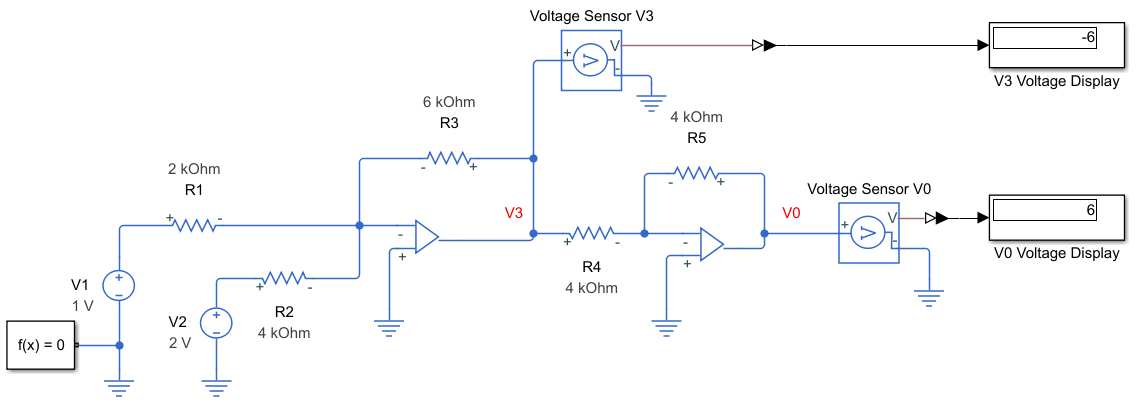

#### Exercise 2: Difference Operational Amplifier Circuit

In the following circuit

- Write a node equation at node $$V_p$  to find $$V_p$.

- Write a node equation at node $$V_n$  to find $$V_0$.

- Find  $$V_p$ and $$V_0$ when  $$V_1=2.5V$ and $$V_2=1.5V$

- Find  $$V_p$and $$V_0$ when  $$V_1=0V$ and $$V_2=2V$

                  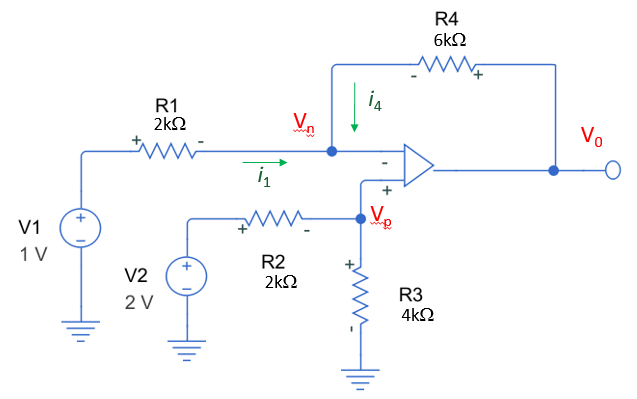

 **Solution**

       1. Write a node equation at Node $$V_p$  and find it   

       2. Write a node equation at Node $$V_n$  and find $$V_0$  

            Use MATLAB** solve** function to find $V_p$  and  $V_0$  .   

u = symunit;

% Given Values
% V1 = 1*u.V
% V2 = 2.5*u.V
% R1 = ?? *u.kOhm; R2 = 4*u.kOhm; R3 = 6*u.kOhm; R4 = 4*u.kOhm;
% Unknown Node voltage V3
syms Vp V0;

% Node equations and solution
  

3.  Change $$V_1=2.5V$ and $$V_2=1.5V$ and find  $$V_p$ and $$V_0$

4.  Change $$V_1=0V$ and $$V_2=2V$ and find  $$V_p$ and $$V_0$

**Alternative Solution**: Take two node equations and simplify them

 Let's use MATLAB  to find $V_p$ and $V_0$     

u = symunit;
% Given Values


% Unknown Node voltage Vp

% Unknown Node voltage Vp


Simulate  this exercise using MATLAB Simulink to chek your values. 

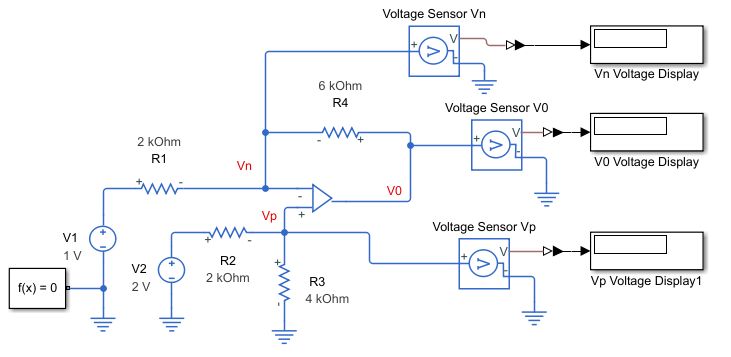

===================

### **Case 3 :** Current Amplifier

Using input current sourse  to amplify the currrent at the output of operational  amplifiler.  

#### Example 3. Current Amplifier

Find $V_2$,$V_0$ and $i_0$ in the circuit shown 

                        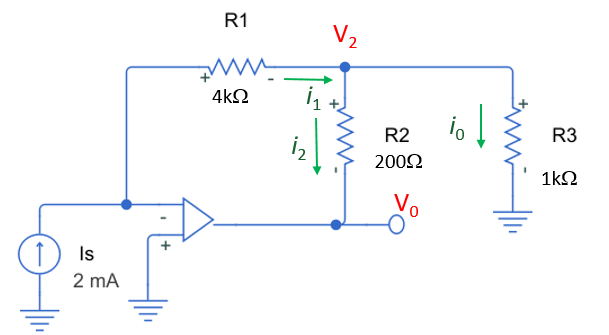     

   **Solution:**      Since $i_n=0$, current  $i_1=I_s$. Voltage $V_2$ can be calculated  $V_2=-I_sR_1$

                        The current $i_0$ through $R_3$ is given by.  

                                      
$$i_0=\frac{V_2}{R_3}=-\frac{R_1}{R_3}I_s$$


                      The current $i_2$ can be calculated 

                                    
$$i_2=i_1-i_0=I_s-i_0=I_s+\frac{R_1}{R_3}I_s=\Big(1+\frac{R_1}{R_3}\Big)I_s$$


                The output voltage $V_0$ of the op amp is given by

                                     
$$V_0=V_2-R_2i_2= -I_sR_1-R_2\Big(1+\frac{R_1}{R_3}\Big)I_s=-\Big(1+\frac{R_2}{R_3}+\frac{R_2}{R_1}\Big)R_1I_s$$


      We have three equations and three unknowns. Use MATLAB** solve** function to find $I_1, I_2$and $I_3$  as follow.    

u = symunit;
% Given Values
Is = 2*u.mA;
R1 = 4*u.kOhm; R2 = 200*u.Ohm; R3 = 1*u.kOhm;

% Calculations
i1 = Is;
V2=-i1*R1;
i0=V2/R3;
i2=i1-i0;
V0=V2-R2*i2;

V2 = rewrite(V2,u.V);
V0 = rewrite(V0,u.V);

Display each values in 4 significant decimal digits

V2 = vpa(V2,5)

$$V2 = -8.0\,V$$

V0 = vpa(V0,5)

$$V0 = -10.0\,V$$

i0 = vpa(i0,5)

$$i0 = -8.0\,\mathrm{mA}$$

Finally we have the following values

$V_2=-8.0V$,   $V_0 =-10.0 V$,  $V_3 =3.5616 V$  ,  $i_0=-8mA$

Circuit simulation is given in the following MATLAB Simulink [./Simulink\Example_3.slx](matlab:open('./Simulink\Example_3.slx'))

    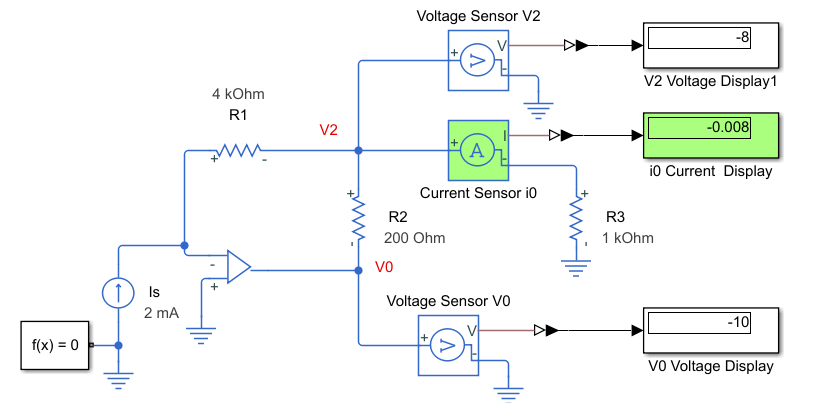

#### Exercise 3. Current Amplifier

Find $V_0$ and $i_0$ in the circuit shown 

                        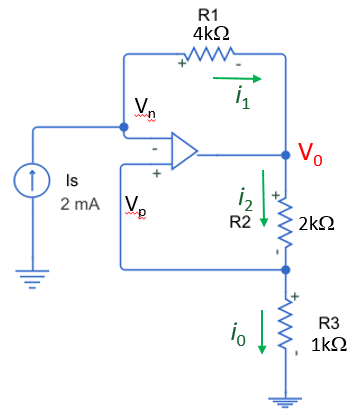     

   **Solution:**   Find current $i_1$  through $R_3$

                     Find the voltage $V_0$ at node $V_0$ function of $i_2 $and $V_p$

                      The current $i_2 $ through $R_2$

                      The current $i_2$ can be calculated 

                      Since the current flowing into the op amp  is zero, the current $i_0 $ through $R_3$ is equal to current $i_2 $ through $R_2$

      Use MATLAB  to find $V_0$ and $i_0$    

u = symunit;
% Given Values


% Calculations


%  V0 = rewrite(V0,u.V);

Display each values in 4 significant decimal digits

V0 = vpa(V0,5)

$$V0 = -10.0\,V$$

i0 = vpa(i0,5)

$$i0 = -8.0\,\mathrm{mA}$$

     Simulate  this exercise using MATLAB Simulink to chek your values. 

### 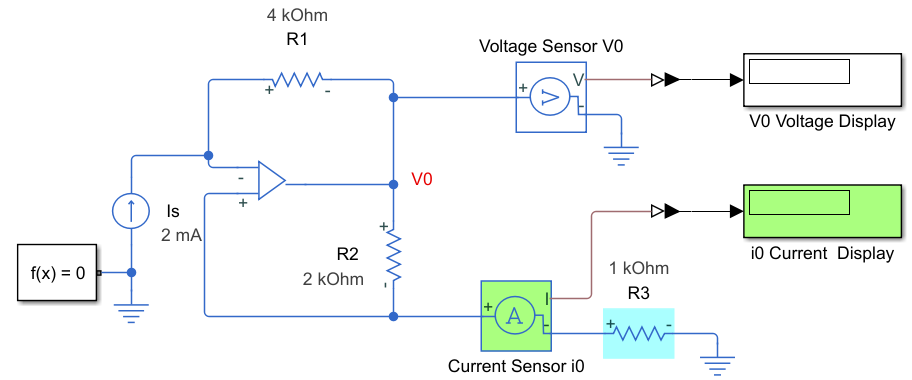

#### Example 4. Multi Operational Amplifiers

Find Node voltages $V_{n1}$,$V_3$, and $V_0$  in the circuit shown

                        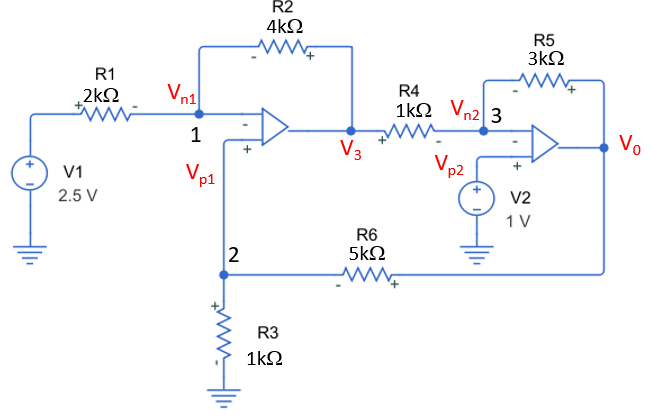     

   **Solution:**      Apply Node analysis at Node 1 

                             
$$\frac{V_1-V_{n1}}{R_1}+\frac{V_3-V_{n1}}{R_2}=0$$


                        Apply Node analysis at Node 2 

                           
$$-\frac{V_{p1}-0}{R_3}+\frac{V_0-V_{p1}}{R_6}=0$$


                        Apply Node analysis at Node 3

                           
$$\frac{V_3-V_{n2}}{R_4}+\frac{V_0-V_{n2}}{R_5}=0$$


                Due to a virtual short, we have $V_{n1}=V_{p1}$  and $V_{n2}=V_{p2}=V2=1V$

      We have three equations and three unknowns. Use MATLAB** solve** function to find $V_{n1}$,$V_3$, and $V_0$ as follow.    

u = symunit;
% Given Values
V1 = 2.5*u.V; V2 = 1*u.V; 
R1 = 2*u.kOhm; R2 = 4*u.kOhm; R3 = 1*u.kOhm; R4 = 1*u.kOhm; R5 = 3*u.kOhm; R6 = 5*u.kOhm;

% Unknown Node voltages
syms Vn1 V3 V0;

% Node equations and solutions
[V0, V3, Vn1] = solve ((V1-Vn1)/R1+(V3-Vn1)/R2==0, -Vn1/R3+(V0-Vn1)/R6==0, (V3-V2)/R4+(V0-V2)/R5==0);

Vn1 = rewrite(Vn1,u.V)

$$Vn1 = \frac{19}{15}\,V$$

V3 = rewrite(V3,u.V)

$$V3 = -\frac{6}{5}\,V$$

V0 = rewrite(V0,u.V)

$$V0 = \frac{38}{5}\,V$$

Display each values in 4 significant decimal digits

Vn1 = vpa(Vn1,5)

$$Vn1 = 1.2667\,V$$

V3 = vpa(V3,5)

$$V3 = -1.2\,V$$

V0 = vpa(V0,5)

$$V0 = 7.6\,V$$

**Alternative Solution**: The node equations can be rearranged  in unknown variables and put into a matrix form as

     Node 1 equation 

            $\frac{V_1}{R_1}-\frac{V_{n1}}{R_1}+\frac{V_3}{R_2}-\frac{V_{n1}}{R_2}=0$,         $-\Big(\frac{1}{R_1}-\frac{1}{R_2}\Big)V_{n1}+\frac{1}{R_2}V_3=-\frac{1}{R_1}V_1$

    Node 2 equation 

            $-\frac{1}{R_3}V_{n1}+\frac{1}{R_6}V_0-\frac{1}{R_6}V_{n1}=0$,         $-\Big(\frac{1}{R_3}+\frac{1}{R_6}\Big)V_{n1}+\frac{1}{R_6}V_0=0$  

      Node 3 equation 

                  $\frac{1}{R_4}V_3-\frac{1}{R_4}V_2+\frac{1}{R_5}V_0-\frac{1}{R_5}V_2=0$, $\frac{1}{R_4}V_3+\frac{1}{R_5}V_0=\Big(\frac{1}{R_4}+\frac{1}{R_5}\Big)V_2$

        
$$\left[ \begin{array} { c c } {-\Big(\frac{1}{R_1} +\frac{1}{R_2}\Big)} & {\frac{1}{R_2} } & {0 } \\ {-\Big(\frac{1}{R_3}+\frac{1}{R_6}\Big)} & {0 } &  {\frac{1}{R_6} } \\  {0} & {\frac{1}{R_4 } &  {\frac{1}{R_5} } \end{array} \right] \left[ \begin{array} { l } { V _ {1} } \\ { V _ 3 } \\V_0 \end{array} \right] = \left[ \begin{array} { c } { -\frac{1}{R_1}}V_1 \\ { 0 }\\ {\Big(\frac{1}{R_4}+\frac{1}{R_5}\Big) V_2\end{array} \right]$$


This matrix equation can be solved using MATLAB as shown

%Matrix AxV=b
A = [-(1/R1+1/R2) 1/R2 0; -(1/R3+1/R6) 0 1/R6; 0 1/R4 1/R5]

$$A = \left(\begin{array}{ccc} -\frac{3}{4}\,\frac{1}{\mathrm{k\Omega}} & \frac{1}{4}\,\frac{1}{\mathrm{k\Omega}} & 0\\ -\frac{6}{5}\,\frac{1}{\mathrm{k\Omega}} & 0 & \frac{1}{5}\,\frac{1}{\mathrm{k\Omega}}\\ 0 & \frac{1}{\mathrm{k\Omega}} & \frac{1}{3}\,\frac{1}{\mathrm{k\Omega}} \end{array}\right)$$

b = [-(1/R1)*V1; 0; (1/R4+1/R5)*V2]

$$b = \left(\begin{array}{c} -\frac{5}{4}\,\frac{V}{\mathrm{k\Omega}}\\ 0\\ \frac{4}{3}\,\frac{V}{\mathrm{k\Omega}} \end{array}\right)$$

V = A\b;

Vn1 = V(1);
Vn1 = rewrite(Vn1,u.V)

$$Vn1 = \frac{19}{15}\,V$$

V3 = V(2)

$$V3 = -\frac{6}{5}\,V$$

V3 = simplify(V3)

$$V3 = -\frac{6}{5}\,V$$

V0 = V(3)

$$V0 = \frac{38}{5}\,V$$

V0 = simplify(V0)

$$V0 = \frac{38}{5}\,V$$

Display each values in 4 significant decimal digits

Vn1 = vpa(Vn1,5)

$$Vn1 = 1.2667\,V$$

V3 = vpa(V3,5)

$$V3 = -1.2\,V$$

V0 = vpa(V0,5)

$$V0 = 7.6\,V$$

Finally we have the following values

$V_{n1}=1.2667V$,   $V_3 =-1.2V$,  $V_0 =7.6 V$  

Circuit simulation is given in the following MATLAB Simulink [./Simulink\Example_4.slx](matlab:open('./Simulink\Example_4.slx'))

    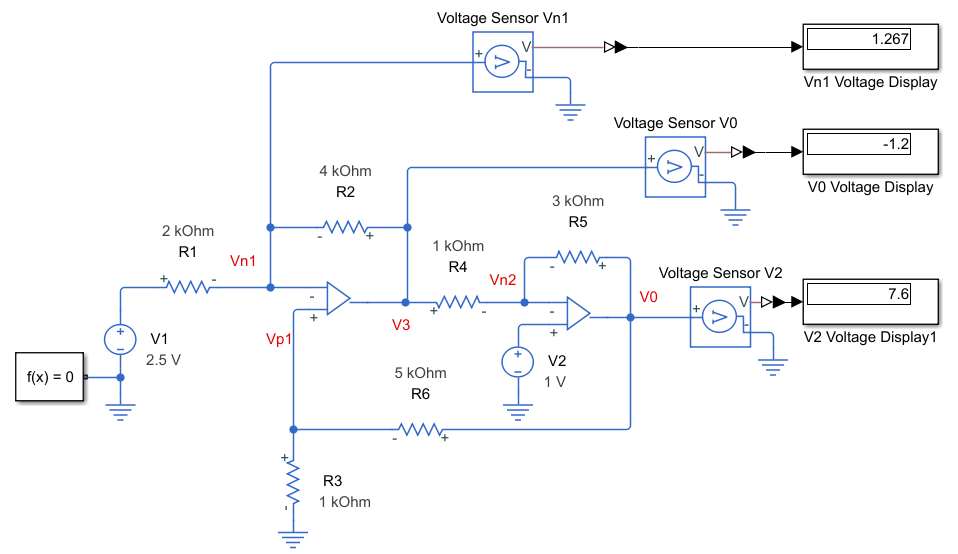

#### Exercise 3.  Multi Operational Amplifiers

Find Node voltages $V_{n1}$,$V_3$, and $V_0$  in the circuit shown 

                        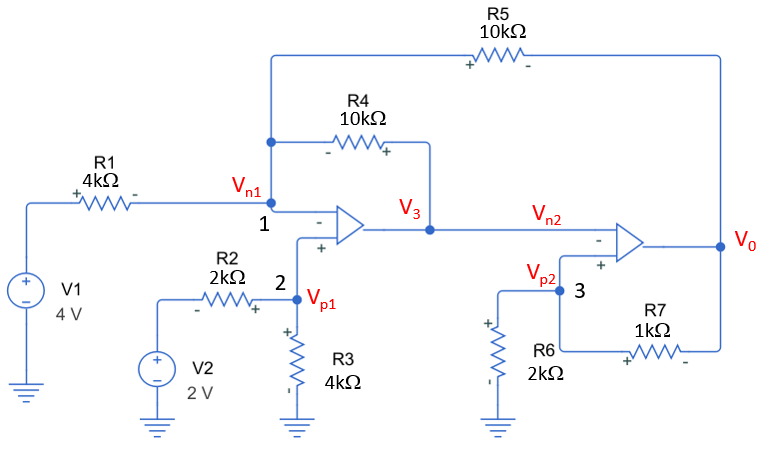     

   **Solution:**      Apply Node analysis at Node 1 

                        Apply Node analysis at Node 2 

                        Apply Node analysis at Node 3

                Due to a virtual short, we have $V_{n1}=V_{p1}$  and $V_{n2}=V_{p2}$

      We have three equations and three unknowns. Use MATLAB** solve** function to find $V_{n1}$,$V_3$, and $V_0$ as follow.    

u = symunit;
% Given Values


% Unknown Node voltages
syms Vn1 V3 V0;

% Node equations and solutions
% [V0, V3, Vn1] = solve ();

% Vn1 = rewrite(Vn1,u.V)
% V3 = rewrite(V3,u.V)
% V0 = rewrite(V0,u.V)


Display each values in 4 significant decimal digits

% Vn1 = vpa(Vn1,5)
% V3 = vpa(V3,5)
% V0 = vpa(V0,5)

**Alternative Solution**: Simplify the node equations  in unknown variables and put into a matrix form as

This matrix equation can be solved using MATLAB as shown

%Matrix AxV=b
% A = [? ? ?;? ? ?; ? ? ?]
% b = [?; ? ;? ]
% V = A\b;

Vn1 = V(1);
Vn1 = rewrite(Vn1,u.V)

$$Vn1 = \frac{19}{15}\,V$$

V3 = V(2)

$$V3 = -\frac{6}{5}\,V$$

V3 = simplify(V3)

$$V3 = -\frac{6}{5}\,V$$

V0 = V(3)

$$V0 = \frac{38}{5}\,V$$

V0 = simplify(V0)

$$V0 = \frac{38}{5}\,V$$

Display each values in 4 significant decimal digits

Vn1 = vpa(Vn1,5)

$$Vn1 = 1.2667\,V$$

V3 = vpa(V3,5)

$$V3 = -1.2\,V$$

V0 = vpa(V0,5)

$$V0 = 7.6\,V$$

  Simulate  this exercise using MATLAB Simulink to chek your values. 

### 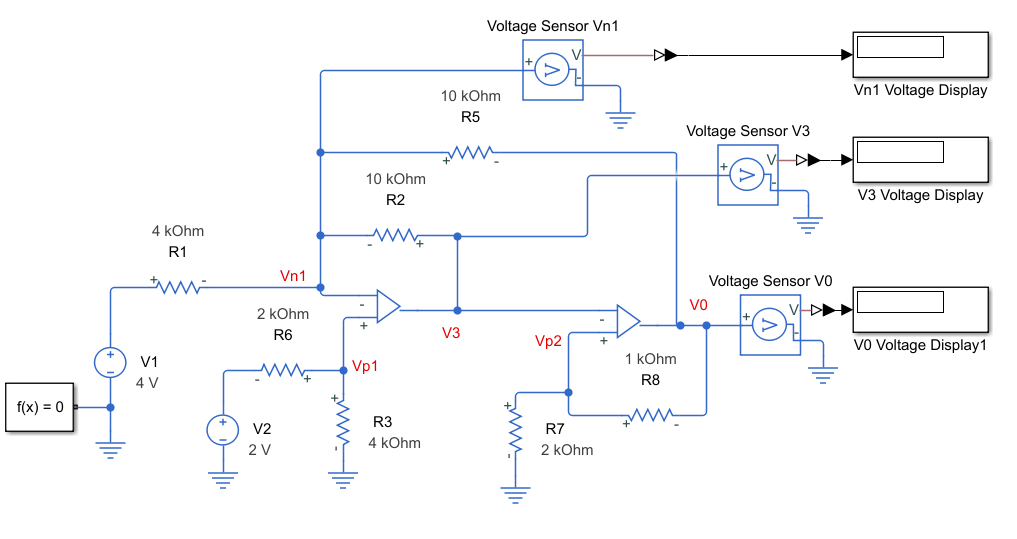

### References/Additional Info

***Electric Circuits***, James Kang, 1st ed. Cengage Learning, 2018